clear;clc;
load("PointFangXing.mat")
PAB = [-0.176,-0.06,0.6];
P_bound1 = [-0.142,0.47,0.061];
P_bound2 = [0.57,0.28,0.138];


PlaneParaIn = [];
[PlaneParaOut,TrianglePoints] = planefit(face3_transformed, ...
    PlaneParaIn,BoundPoint1,BoundPoint2);

figure;
hold on
scatter3(face3_transformed(1, :), face3_transformed(2, :), face3_transformed(3, :), 'r.');
% plot3(TrianglePoints(1,[1:3,1]),TrianglePoints(2,[1:3,1]),TrianglePoints(3,[1:3,1]))
% plot3(TrianglePoints(1,[4:6,4]),TrianglePoints(2,[4:6,4]),TrianglePoints(3,[4:6,4]))


%% 平面2
[PlaneParaOut2,TrianglePoints2] = planefit(face1_transformed, ...
    PlaneParaOut,BoundPoint1,BoundPoint2);

scatter3(face1_transformed(1, :), face1_transformed(2, :), face1_transformed(3, :), 'g.');
% plot3(TrianglePoints2(1,[1:3,1]),TrianglePoints2(2,[1:3,1]),TrianglePoints2(3,[1:3,1]))
% plot3(TrianglePoints2(1,[4:6,4]),TrianglePoints2(2,[4:6,4]),TrianglePoints2(3,[4:6,4]))
% plot3(TrianglePoints2(1,[7:9,7]),TrianglePoints2(2,[7:9,7]),TrianglePoints2(3,[7:9,7]))
% plot3(TrianglePoints2(1,[10:12,10]),TrianglePoints2(2,[10:12,10]),TrianglePoints2(3,[10:12,10]))


%% 平面3
[PlaneParaOut3,TrianglePoints3] = planefit(face4_transformed, ...
    PlaneParaOut2,BoundPoint1,BoundPoint2);

scatter3(face4_transformed(1, :), face4_transformed(2, :), face4_transformed(3, :), 'b.');
% plot3(TrianglePoints3(1,[1:3,1]),TrianglePoints3(2,[1:3,1]),TrianglePoints3(3,[1:3,1]))
% plot3(TrianglePoints3(1,[4:6,4]),TrianglePoints3(2,[4:6,4]),TrianglePoints3(3,[4:6,4]))
% plot3(TrianglePoints3(1,[7:9,7]),TrianglePoints3(2,[7:9,7]),TrianglePoints3(3,[7:9,7]))
% plot3(TrianglePoints3(1,[10:12,10]),TrianglePoints3(2,[10:12,10]),TrianglePoints3(3,[10:12,10]))
% plot3(TrianglePoints3(1,[13:15,13]),TrianglePoints3(2,[13:15,13]),TrianglePoints3(3,[13:15,13]))
% plot3(TrianglePoints3(1,[16:18,16]),TrianglePoints3(2,[16:18,16]),TrianglePoints3(3,[16:18,16]))

%% 平面4
[PlaneParaOut4,TrianglePoints4] = planefit(face2_transformed, ...
    PlaneParaOut3,BoundPoint1,BoundPoint2);

scatter3(face2_transformed(1, :), face2_transformed(2, :), face2_transformed(3, :), 'm.');
plot3(TrianglePoints4(1,[1:3,1]),TrianglePoints4(2,[1:3,1]),TrianglePoints4(3,[1:3,1]))
plot3(TrianglePoints4(1,[4:6,4]),TrianglePoints4(2,[4:6,4]),TrianglePoints4(3,[4:6,4]))
plot3(TrianglePoints4(1,[7:9,7]),TrianglePoints4(2,[7:9,7]),TrianglePoints4(3,[7:9,7]))
plot3(TrianglePoints4(1,[10:12,10]),TrianglePoints4(2,[10:12,10]),TrianglePoints4(3,[10:12,10]))
plot3(TrianglePoints4(1,[13:15,13]),TrianglePoints4(2,[13:15,13]),TrianglePoints4(3,[13:15,13]))
plot3(TrianglePoints4(1,[16:18,16]),TrianglePoints4(2,[16:18,16]),TrianglePoints4(3,[16:18,16]))
plot3(TrianglePoints4(1,[19:21,19]),TrianglePoints4(2,[19:21,19]),TrianglePoints4(3,[19:21,19]))
plot3(TrianglePoints4(1,[22:24,22]),TrianglePoints4(2,[22:24,22]),TrianglePoints4(3,[22:24,22]))

box on
grid on
axis equal




% 计算轴线方向
Pdd = TrianglePoints4(:,[1:3,6,9,16:18])

Pdd =    -0.5850   -0.5848   -0.0829   -0.0826    0.2824    0.7830    0.2826    0.7833
    0.2859    0.2856   -0.5835   -0.5840    0.7864   -0.0843    0.7861   -0.0848
    0.5999   -0.4007    0.5995   -0.4000    0.6012    0.6008   -0.4005   -0.3998


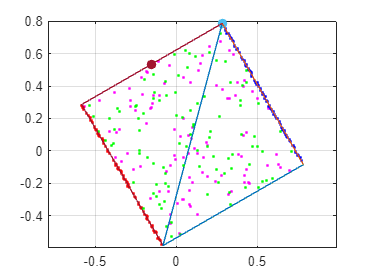

Tao1 = (Pdd(:,3)-Pdd(:,1))./norm(Pdd(:,3)-Pdd(:,1));
Tao2 = (Pdd(:,4)-Pdd(:,2))./norm(Pdd(:,4)-Pdd(:,2));
Tao3 = (Pdd(:,6)-Pdd(:,5))./norm(Pdd(:,6)-Pdd(:,5));
Tao4 = (Pdd(:,8)-Pdd(:,7))./norm(Pdd(:,8)-Pdd(:,7));
Tao = (Tao1+Tao2+Tao3+Tao4)./4;

% 计算中点
temp1 = (Pdd(:,2)+Pdd(:,5))./2;
temp2 = (Pdd(:,1)+Pdd(:,7))./2;
P1 = (temp1+temp2)./2;

temp3 = (Pdd(:,3)+Pdd(:,8))./2;
temp4 = (Pdd(:,4)+Pdd(:,6))./2;
P2 = (temp3+temp4)./2;

% 计算长宽
temp5 = (Pdd(:,1)+Pdd(:,5))./2;
upp = (Pdd(:,7)+Pdd(:,5))./2;
b = 2*dist(P1,temp5');
h = 2*dist(P1,upp');

scatter3(upp(1),upp(2),upp(3),50,'filled')
scatter3(P1(1),P1(2),P1(3),50,'filled')

## 先平移P1平移到000

% 面上点
F1move= face1_transformed - repmat(P1,1,size(face1_transformed,2));
F2move= face2_transformed - repmat(P1,1,size(face2_transformed,2));
F3move= face3_transformed - repmat(P1,1,size(face3_transformed,2));
F4move= face4_transformed - repmat(P1,1,size(face4_transformed,2));

% P1
P1move = [0,0,0];
% upp
uppmove = upp-P1; %平移后的上面点
% Tao 不变

%PAB
% PABmove = PAB-P1;



## p1-t6为上，构建旋转矩阵

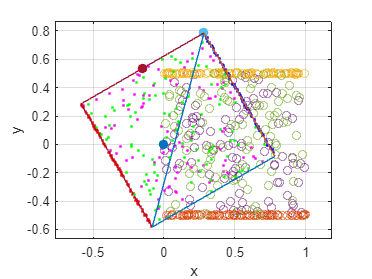



% 构建旋转矩阵1,pt6转到z轴
theta1 = atan2(norm(cross([0, 0, 1], uppmove)), dot([0, 0, 1], uppmove));
v1 = cross([0, 0, 1],uppmove) / norm(cross([0, 0, 1], uppmove));
rot1 = myvrrotvec2mat([v1, theta1]);

% Tao旋转rot1
TaoRot1 = Tao'*rot1;


% 构建旋转矩阵2,taorot1转到x轴
theta2 = atan2(norm(cross([1, 0, 0], TaoRot1)), dot([1, 0, 0], TaoRot1));
v2 = cross([1, 0, 0],TaoRot1) / norm(cross([1, 0, 0], TaoRot1));
rot2 = myvrrotvec2mat([v2, theta2]);


% 总的旋转矩阵 ROT
ROT = rot1*rot2;



% 验证
F2rot1 = F1move'*ROT;
F3rot1 = F2move'*ROT;
F4rot1 = F3move'*ROT;
F1rot1 = F4move'*ROT;
rotupp6 = uppmove'*ROT;

scatter3(rotupp6(1),rotupp6(2),rotupp6(3),50,'filled')
scatter3(F2rot1(:,1),F2rot1(:,2),F2rot1(:,3))
scatter3(F3rot1(:,1),F3rot1(:,2),F3rot1(:,3))
scatter3(F4rot1(:,1),F4rot1(:,2),F4rot1(:,3))
scatter3(F1rot1(:,1),F1rot1(:,2),F1rot1(:,3))
xlabel('x')
ylabel('y')


% 轴向平移旋转
Taorot1 = Tao'*rot1;






% 中间点 测试点
PAB = (Pdd(:,6)+Pdd(:,7))./2;
% 平移+旋转
PABmove = PAB-P1;
PABrot = PABmove'*rot1;



